Face Masks: Comparing cloth and N95 surgical masks in their effectiveness

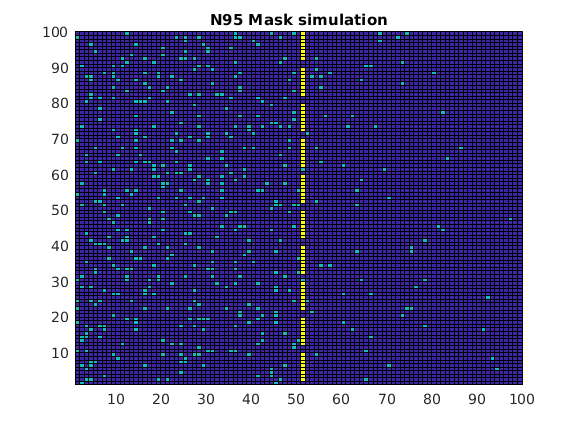

particleCap = 500;
particleNum = 0;
gridSize = 100;
timeSteps = 1000;
v = VideoWriter("Face Mask/facemask_vid");
open(v);

% N95

% Create random particles on the grid
grid = zeros(gridSize, gridSize);
particles = zeros(2,particleCap);
particleValue = 1;
while particleNum < particleCap
    x = randi([1 gridSize]);
    y = randi([1 gridSize/2]);
    if grid(x,y) ~= 1
        grid(x,y) = particleValue;
        particleNum = particleNum + 1;
        particles(1,particleNum) = x;
        particles(2,particleNum) = y;
    end
end

% Create the mask barrier
mask1Loc = 51;
mask1HoleFreq = 10;
grid = buildMask(grid, gridSize, mask1Loc, mask1HoleFreq);

% Timesteps
penetratedParticlesN95 = zeros(1,timeSteps);
for i = 0:timeSteps
    [particles, grid] = moveParticles(particles,grid,gridSize);
    count = 0;
    for j = 1: particleNum
        if(particles(2,j) > mask1Loc)
            count = count + 1;
        end
    end
    penetratedParticlesN95(1,i + 1) = count;
    pause(0.1);
    figure(1);
    
    xlim([0, gridSize]);
    ylim([0,gridSize]);
    frame = getframe(gcf);
    writeVideo(v, frame);
    pcolor(grid);
end
title("N95 Mask simulation");

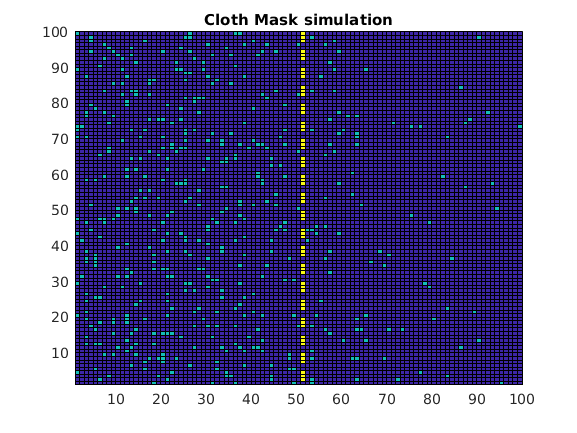

close(v);

% CLOTH

% Create random particles on the grid
grid = zeros(gridSize, gridSize);
particleNum = 0;
while particleNum < particleCap
    x = randi([1 gridSize]);
    y = randi([1 gridSize/2]);
    if grid(x,y) ~= 1
        grid(x,y) = particleValue;
        particleNum = particleNum + 1;
        particles(1,particleNum) = x;
        particles(2,particleNum) = y;
    end
end

% Create the mask barrier
mask2Loc = 51;
mask2HoleFreq = 5;
grid = buildMask(grid, gridSize, mask2Loc, mask2HoleFreq);

% Timesteps
penetratedParticlesCloth = zeros(1,timeSteps);
for i = 0:timeSteps
    [particles, grid] = moveParticles(particles,grid,gridSize);
    count = 0;
    for j = 1: particleNum
        if(particles(2,j) > mask2Loc)
            count = count + 1;
        end
    end
    penetratedParticlesCloth(1,i + 1) = count;
    pause(.01);
    figure(2);
    pcolor(grid)    
end
title("Cloth Mask simulation");

figure(3);

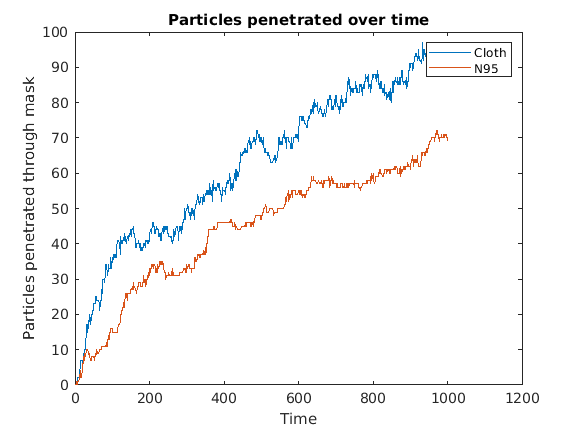

plot(penetratedParticlesCloth)
hold on
plot(penetratedParticlesN95)
legend("Cloth", "N95");
title("Particles penetrated over time");
ylabel("Particles penetrated through mask");
xlabel("Time");

function [particles, grid] = moveParticles(particles,grid, gridSize)
    % remove old particles
    for i = 1:length(particles)
        grid(particles(1,i), particles(2,i)) = 0;
    end
    
    % Change every particles position
    for i = 1: length(particles)
        x = 1;
        y = 2;
        
        % Determine change delta
        xChange = randi([-1 1]);
        yChange = randi([-1 1]);
    
        newX = particles(x,i) + xChange;
        newY = particles(y,i) + yChange;
        % Walls to not go through
        if newX < 1
            newX = 1;
        end
        if newX > gridSize
            newX = gridSize;
        end
        if newY < 1
            newY = 1;
        end
        if newY > gridSize
            newY = gridSize;
        end
        valueAtNewPos = grid(newX, newY);
        % Recalculate if in an occupied space
        while(valueAtNewPos ~= 0)
            xChange = randi([-1 1]);
            yChange = randi([-1 1]);
            newX = particles(x,i) + xChange;
            newY = particles(y,i) + yChange;
            if newX < 1
                newX = 1;
            end
            if newX > gridSize
                newX = gridSize;
            end
            if newY < 1
                newY = 1;
            end
            if newY > gridSize
                newY = gridSize;
            end
            valueAtNewPos = grid(newX, newY);
        end
        
        particles(x,i) = newX;
        particles(y,i) = newY;
    end
    % update grid
    for i = 1:length(particles)
        grid(particles(x,i), particles(y,i)) = 1;
    end
end

function grid = buildMask(grid,gridSize,maskLoc, barrierHoleFrequency)
    maskValue = 2;
    barrierLocation = maskLoc;
    % Create barrier at the Y location with holes 2 spaces wide
    for i = 1:gridSize
        if (mod(i,barrierHoleFrequency) == 0 || mod(i,barrierHoleFrequency) == 1)
            continue;
        end
        grid(i,barrierLocation) = maskValue;
    end
end